# Drag Rake Wind Tunnel Testing Data Analysis Report

#### Bennett Diamond -- 7.29.2020

    This report will examine the effectiveness of Akaflieg SLO's Drag Rake and will compare it's drag results to independently calculated drag data for accuracy. 

### Part 1: Varying Speed with Constant Angle of Attack

    Data was collected in the Cal Poly Low Speed Wind Tunnel and is imported to Matlab below. The file format is dr (representing drag rate) _ number (representing tunnel speed in m/s) _ angle of attack (in degrees) and run number (represented by letter).

% Loading in testing data
clc, clear

% constants
r = 273; % J/kg-k
L = 0.069; % m - rake length

filenames = {'dr_11.5_0c.mat', 'dr_16_0c.mat', 'dr_22_0c.mat',...
    'dr_27_0c.mat', 'dr_32_0c.mat', 'dr_37_0c.mat', 'dr_42_0c.mat';... 
    'dr_11.5_0d.mat', 'dr_16_0d.mat', 'dr_22_0d.mat', 'dr_27_0d.mat',...
    'dr_32_0d.mat', 'dr_37_0d.mat', 'dr_42_0d.mat'};

graph_filenames = {'dr_11.5_0c.png', 'dr_16_0c.png', 'dr_22_0c.png',...
    'dr_27_0c.png', 'dr_32_0c.png', 'dr_37_0c.png', 'dr_42_0c.png';... 
    'dr_11.5_0d.png', 'dr_16_0d.png', 'dr_22_0d.png', 'dr_27_0d.png',...
    'dr_32_0d.png', 'dr_37_0d.png', 'dr_42_0d.png'};

After the data was loaded in, the raw pressure data was plotted so it could be visualized. To see the plots, change plotRawPressureData to TRUE.

plotRawPressureData = false; % WARNING: will create 15+ plots if TRUE
savePressurePlots = false;

for jj = 1:length(filenames)
    for ii = 1:2
        load(filenames{ii,jj})
        
        if plotRawPressureData == true
            figure
            plot(t, P(:,1))
            hold on
            plot(t, P(:,3))
            plot(t, P(:,4))
            plot(t, P(:,5))
            plot(t, P(:,6))
            title(filenames{ii,jj})
            xlabel('time (s)')
            ylabel('Pressure (pa)')
            legend('total', 'bot free', 'bot rake', 'top rake', 'top free')
            
            if saveRawPressurePlots == true
                saveas(gcf,graph_filenames{ii,jj})
            end
        end
        
        % finding density and average tunnel speed
        rho = P_amb/(r*T); % kg/m^3
        speeds(jj) = mean(V);
        
        % calculating velocity at rake and freestream tubes - NOTE: GAUGE
        % PRESSURE hence static pressure not needed
        v_inf_top(ii,jj) = sqrt((2/rho)*(mean(P(:,6))));
        v_rake_top(ii,jj) = sqrt((2/rho)*(mean(P(:,5))));
        v_rake_bot(ii,jj) = sqrt((2/rho)*(mean(P(:,4))));
        v_inf_bot(ii,jj) = sqrt((2/rho)*(mean(P(:,3))));
        v_tunnel(ii,jj) = sqrt((2/rho)*(mean(P(:,1))));
        
        Pdiff_top(ii,jj) = mean(P(:,6)) - mean(P(:,5));
        Pdiff_bot(ii,jj) = mean(P(:,3)) - mean(P(:,4));
        Pdiff(ii,jj) = (Pdiff_top(ii,jj) + Pdiff_bot(ii,jj))/2; % finding mean (total) Pdiff
        
        clear P P_amb T V
        
    end
end

    Once the raw data is visualized, the raw data can then be turned into more intuitive information. The pressures measured in the rake are normally stagnation pressures. However, the pressure aquisition system for the tunnel normalizes all pressures to the wall static pressure. This means that the pressures read on the rake are guage pressures with respect to the tunnel static pressure (assuming no pressure loss along the tunnel wall to the test section). With these pressure differentials between a static pressure port and stagnation pressure ports on the rake, the airspeed at each rake area (freestream and wing boundary layer airspeeds at the top and bottom of the wing) can be calculated and compared. The wind tunnel airspeed, taken from the tunnel pitot at the tunnel inlet is also calculated, as well as the pressure differentials between the rake body parts. The pressure differentials are critical because they are what will be measured during normal opperation in flight. Therefore, it is critical that they provide accurate information.

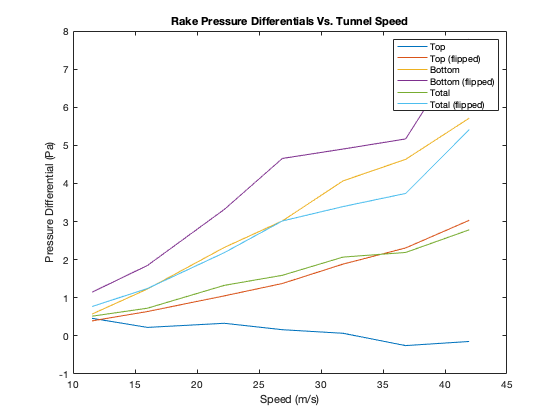

figure % calculated velocities vs tunnel speed
plot(speeds, Pdiff_top(1,:))
hold on
plot(speeds, Pdiff_top(2,:))
plot(speeds, Pdiff_bot(1,:))
plot(speeds, Pdiff_bot(2,:))
plot(speeds, Pdiff(1,:))
plot(speeds, Pdiff(2,:))

title('Rake Pressure Differentials Vs. Tunnel Speed')
ylabel('Pressure Differential (Pa)')
xlabel('Speed (m/s)')
legend('Top', 'Top (flipped)', 'Bottom', 'Bottom (flipped)', 'Total',...
    'Total (flipped)')

    With the drag rake pressures and velocities at each part of the drag rake now organized, a method will be used to estimate the wing drag. Although we are concered with the minimization of wing drag rather than wing drag values, finding the wing drag values and correlating them to 3rd party data will further approve the effectiveness of the rake. Anderson's method, from Anderson's Fundamentals of Aerodynamics, uses the airspeeds measured at each part of the drag rake to determine drag force. The equation is shown below:


$$D=\int_L \rho U_{\infty } \left(U_1 -U_{\infty } \right)$$
                                        

where: $\rho$ = air density, $U_{\infty }$ = freestream velocity (freestream velocity at the freestream tube), $U_1$= velocity in the wing boundary layer (veloctiy at the rake), and $L$ = the width of the boundary layer (rake width)

Since we do not know the exact shape of the boundary layer, we approximated it as a triange, which is represented in the image below:

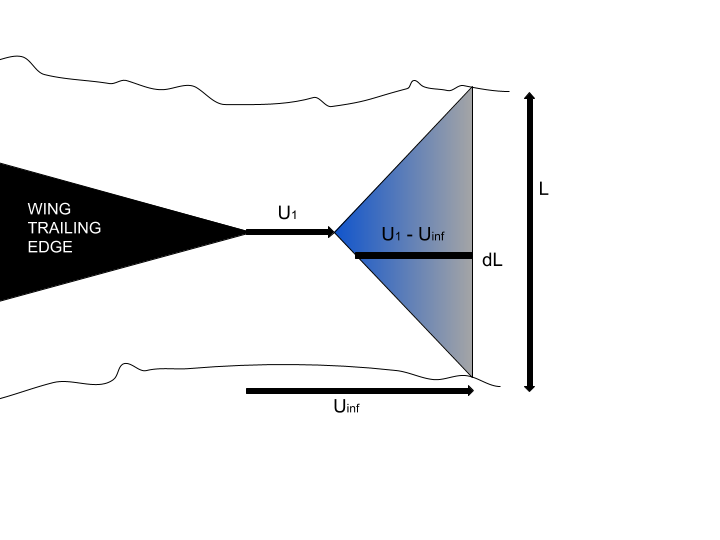

for jj = 1:length(filenames)
    for ii = 1:2
        % calculating drag based on tunnel freestream vel and calc rake
        % freestream velocity
        drag_top_rake(ii,jj) = rho*v_inf_top(ii,jj)*(v_inf_top(ii,jj) - v_rake_top(ii,jj))*L/2;
        drag_bot_rake(ii,jj) = rho*v_inf_bot(ii,jj)*(v_inf_bot(ii,jj) - v_rake_bot(ii,jj))*L/2;
        drag_top_tunnel(ii,jj) = rho*v_tunnel(ii,jj)*(v_tunnel(ii,jj) - v_rake_top(ii,jj))*L/2;
        drag_bot_tunnel(ii,jj) = rho*v_tunnel(ii,jj)*(v_tunnel(ii,jj) - v_rake_top(ii,jj))*L/2;
        
        % summing total drag (rake and tunnel freestream velocity calcs)
        drag_rake(ii,jj) = drag_top_rake(ii,jj) + drag_bot_rake(ii,jj);
        drag_raketunnel(ii,jj) = drag_top_tunnel(ii,jj) + drag_bot_tunnel(ii,jj);
    end
end

The drag values are summed from the upper surface and lower surface of the wing to find the total wing drag. Once all these drag values are determined, they are plotted against tunnel speed. Drag is also calculated using the tunnel airspeed for $U_{\infty }$ for further comparison.

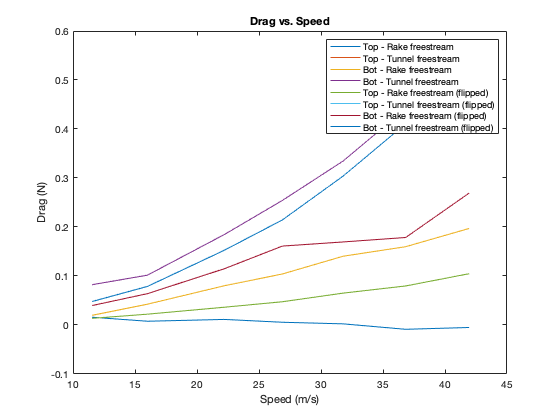

figure % comparing rake and tunnel drags
plot(speeds, drag_top_rake(1,:))
hold on
plot(speeds, drag_top_tunnel(1,:))
plot(speeds, drag_bot_rake(1,:))
plot(speeds, drag_bot_tunnel(1,:))
plot(speeds, drag_top_rake(2,:))
plot(speeds, drag_top_tunnel(2,:))
plot(speeds, drag_bot_rake(2,:))
plot(speeds, drag_bot_tunnel(2,:))
title('Drag vs. Speed')
ylabel('Drag (N)')
xlabel('Speed (m/s)')
legend('Top - Rake freestream', 'Top - Tunnel freestream', ...
    'Bot - Rake freestream', 'Bot - Tunnel freestream',...
    'Top - Rake freestream (flipped)', 'Top - Tunnel freestream (flipped)', ...
    'Bot - Rake freestream (flipped)', 'Bot - Tunnel freestream (flipped)')

    What's quite noticeable from first appearance is that using the wind tunnel's unobstructed stagnation port provides significantly cleaner data that better matches the expected parabolic trend of this kind of test. This shows that the freestream ports are being influenced by the wing and should be spaced farther from the wing. Also apparent is asymmetrical wake from the wing, with the top side freestream tube being greatly affected by the wing, reducing the apparent pressure difference and therefore calculated drag.

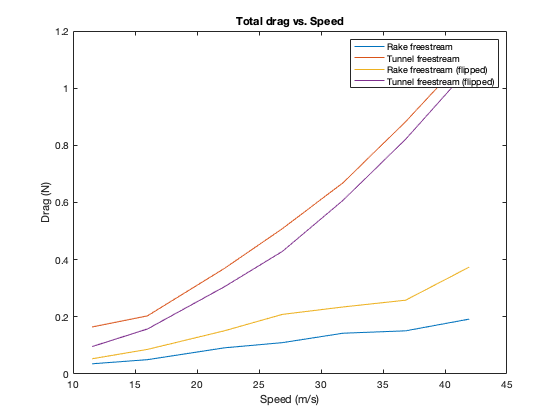

figure % total drags
plot(speeds, drag_rake(1,:))
hold on
plot(speeds, drag_raketunnel(1,:))
plot(speeds, drag_rake(2,:))
plot(speeds, drag_raketunnel(2,:))
title('Total drag vs. Speed')
ylabel('Drag (N)')
xlabel('Speed (m/s)')
legend('Rake freestream', 'Tunnel freestream', 'Rake freestream (flipped)'...
    , 'Tunnel freestream (flipped)')

    In order to compare to the 3rd party analysis, the calculated drag force from Anderson's method is converted from drag force to drag coefficient using the drag coefficient equation. Because the "area" is linear, we will use the length of the drag rake and multiply it by 1 to get area for the equation.

% finding drag coefficient
% using rake freestreams
cd_top_rake = 2*drag_top_rake(1,:) ./ (rho*speeds.^2*L); % cd of top of rake
cd_bot_rake = 2*drag_bot_rake(1,:) ./ (rho*speeds.^2*L); % cd of bot of rake
cd_top_rake_flipped = 2*drag_top_rake(2,:) ./ (rho*speeds.^2*L); % cd of top of rake
cd_bot_rake_flipped = 2*drag_bot_rake(2,:) ./ (rho*speeds.^2*L); % cd of bot of rake

% using tunnel freestream
cd_top_tunnel = 2*drag_top_tunnel(1,:) ./ (rho*speeds.^2*L); % cd of top of rake
cd_bot_tunnel = 2*drag_bot_tunnel(1,:) ./ (rho*speeds.^2*L); % cd of bot of rake
cd_top_tunnel_flipped = 2*drag_top_tunnel(2,:) ./ (rho*speeds.^2*L); % cd of top of rake 
cd_bot_tunnel_flipped = 2*drag_bot_tunnel(2,:) ./ (rho*speeds.^2*L); % cd of bot of rake

% total drags
cd_rake = 2*drag_rake(1,:) ./ (rho*speeds.^2*L); % cd of top of rake
cd_rake_flipped = 2*drag_rake(2,:) ./ (rho*speeds.^2*L); % cd of top of rake

cd_raketunnel = 2*drag_raketunnel(1,:) ./ (rho*speeds.^2*L);
cd_raketunnel_flipped = 2*drag_raketunnel(2,:) ./ (rho*speeds.^2*L);

A sanity check is preformed by graphing the Cd's.

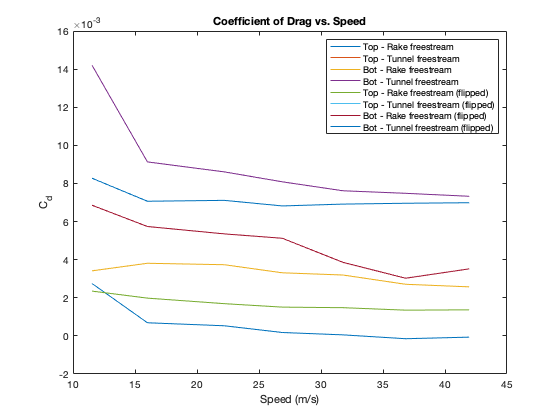

figure % comparing rake and tunnel drags
plot(speeds, cd_top_rake)
hold on
plot(speeds, cd_top_tunnel)
plot(speeds, cd_bot_rake)
plot(speeds, cd_bot_tunnel)
plot(speeds, cd_top_rake_flipped)
plot(speeds, cd_top_tunnel_flipped)
plot(speeds, cd_bot_rake_flipped)
plot(speeds, cd_bot_tunnel_flipped)
title('Coefficient of Drag vs. Speed')
ylabel('C_d')
xlabel('Speed (m/s)')
legend('Top - Rake freestream', 'Top - Tunnel freestream', ...
    'Bot - Rake freestream', 'Bot - Tunnel freestream',...
    'Top - Rake freestream (flipped)', 'Top - Tunnel freestream (flipped)', ...
    'Bot - Rake freestream (flipped)', 'Bot - Tunnel freestream (flipped)')

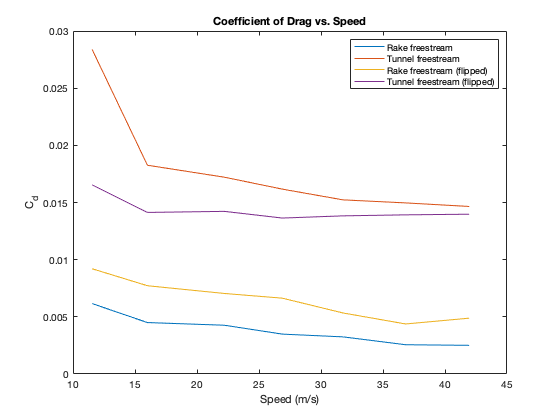


figure % total drags
plot(speeds, cd_rake(1,:))
hold on
plot(speeds, cd_raketunnel(1,:))
plot(speeds, cd_rake_flipped)
plot(speeds, cd_raketunnel_flipped)
title('Coefficient of Drag vs. Speed')
ylabel('C_d')
xlabel('Speed (m/s)')
legend('Rake freestream', 'Tunnel freestream', 'Rake freestream (flipped)'...
    , 'Tunnel freestream (flipped)')

    Now that drag coefficients have been determined and visualized, they can now be compared to 3rd party data from XFLR5. Because of uncertainty with the type of airfoil used in the wind tunnel, 3 different airfoils, the NACA 4412, 2412, and 0012, were analyzed. The analysis was run at 0 deg AoA with no artificial trip of the boundary layer and from Re 1.176e5 to 4.280e5. The results are visualized below.

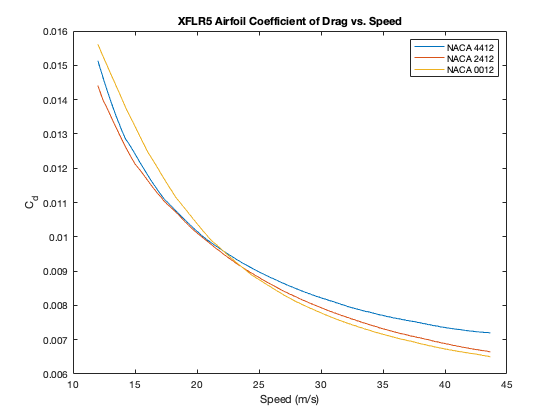

mu = 1.983E-5; % dynamic viscosity of air (since test conditions close to STP assume STP)
l = 0.154; % m - wing length

dr_4412_flat = load('NACA 4412_dr_4412_flat.txt');
dr_2412_flat = load('NACA 2412_dr_2412_flat.txt');
dr_0012_flat = load('NACA 0012_dr_0012_flat.txt');

Re1 = dr_4412_flat(:,2); % reynolds numbers
Re2 = dr_2412_flat(:,2); % reynolds numbers
Re3 = dr_0012_flat(:,2); % reynolds numbers

speeds1 = Re1*mu / (rho*l); % convert to m/s
speeds2 = Re2*mu / (rho*l); % convert to m/s
speeds3 = Re3*mu / (rho*l); % convert to m/s

cd_4412_flat = dr_4412_flat(:,4);
cd_2412_flat = dr_2412_flat(:,4);
cd_0012_flat = dr_0012_flat(:,4);

figure
plot(speeds1,cd_4412_flat)
hold on
plot(speeds2,cd_2412_flat)
plot(speeds3,cd_0012_flat)
title('XFLR5 Airfoil Coefficient of Drag vs. Speed')
xlabel('Speed (m/s)')
ylabel('C_d')
legend('NACA 4412', 'NACA 2412', 'NACA 0012')

Now overlapping the wind tunnel drag coefficients and XFLR5 coefficients:

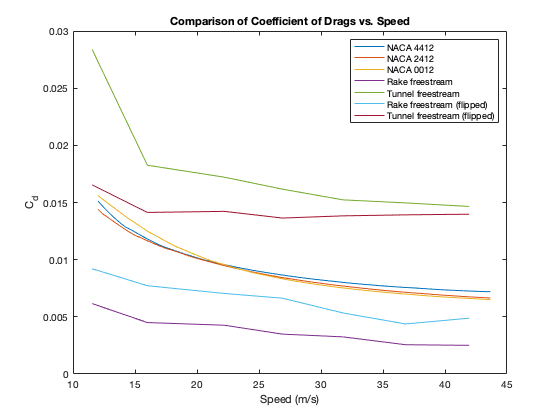

figure
plot(speeds1,cd_4412_flat)
hold on
plot(speeds2,cd_2412_flat)
plot(speeds3,cd_0012_flat)
plot(speeds, cd_rake(1,:))

plot(speeds, cd_raketunnel(1,:))
plot(speeds, cd_rake_flipped)
plot(speeds, cd_raketunnel_flipped)
title('Comparison of Coefficient of Drags vs. Speed')
xlabel('Speed (m/s)')
ylabel('C_d')
legend('NACA 4412', 'NACA 2412', 'NACA 0012', 'Rake freestream',...
    'Tunnel freestream', 'Rake freestream (flipped)',...
    'Tunnel freestream (flipped)')

    While the trends are similar, the drag coefficients are not quite satisfactorily so. Depending on the stagnation velocity source and orientation, the drag coefficients vary wildly, suggesting that the rake was not symmetrical in its build and that the freestream tubes, as discussed earlier, are not entirely in the freestream. While the difference is numbers is frustrating, it is more important to assess the accuracy of determining the minimum drag point by looking at the pressure differences. 

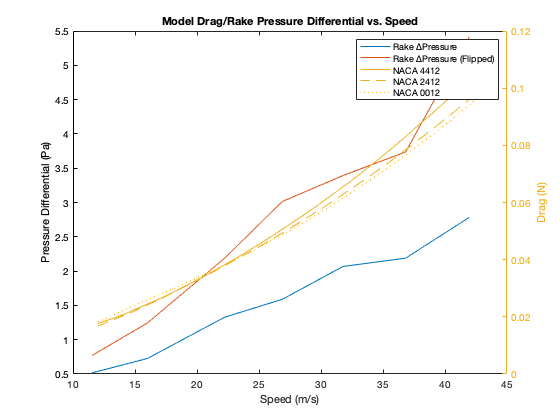

% convering XFLR5 C_d to drag
t = l/12; % m - finding airfoil thickness from length

d_4412_flat = 0.5*rho*t*cd_4412_flat.*speeds1.^2;
d_2412_flat = 0.5*rho*t*cd_2412_flat.*speeds2.^2;
d_0012_flat = 0.5*rho*t*cd_0012_flat.*speeds3.^2;

figure
plot(speeds, Pdiff(1,:))
hold on
plot(speeds, Pdiff(2,:))
ylabel('Pressure Differential (Pa)')
yyaxis right
plot(speeds1, d_4412_flat)
plot(speeds2, d_2412_flat)
plot(speeds3, d_0012_flat)
title('Model Drag/Rake Pressure Differential vs. Speed')
ylabel('Drag (N)')
xlabel('Speed (m/s)')
legend('Rake ∆Pressure', 'Rake ∆Pressure (Flipped)', 'NACA 4412', 'NACA 2412', 'NACA 0012')

    Although the drag numbers are currently wrong (the wing thickness is incorrect), both the drag model and pressure differential data agree that drag is minimized at the slowest speed, which is intuitively and physically true. For further testing, a better drag rake should be constructed that is prefectly symmetrical, as the one used for these tests was not, as evidenced by the diverging lines.

The next test is to evalute at various angles of attack.

### Part 2: Angle of Attack With a Constant Speed

    Many similar steps are taken for reducing the raw pressure data into organized pressure and speed data; therefore these steps will not be discussed. The file naming convention is also the same. To avoid many graphs, leave rawPressurePlots FALSE.

clear % remove variables from part 1 to avoid errors 

rawPressurePlots = false;
savePressurePlots = false;

% constants
r = 273; % J/kg-k
L = 0.069; % m - rake length
AoA = 0:2:20; % deg - AoA vector

filenames = {'dr2_22_0d.mat', 'dr2_22_2d.mat','dr2_22_4d.mat', 'dr2_22_6d.mat', ...
    'dr2_22_8d.mat', 'dr2_22_10d.mat', 'dr2_22_12d.mat', 'dr2_22_14d.mat',...
    'dr2_22_16d.mat', 'dr2_22_18d.mat', 'dr2_22_20d.mat'};

graph_filenames = {'dr2_22_0d.png', 'dr2_22_2d.png','dr2_22_4d.png', 'dr2_22_6d.png', ...
    'dr2_22_8d.png', 'dr2_22_10d.png', 'dr2_22_12d.png', 'dr2_22_14d.png',...
    'dr2_22_16d.png', 'dr2_22_18d.png', 'dr2_22_20d.png'};


for jj = 1:length(filenames)
    load(filenames{jj})
    
    if rawPressurePlots == true
        figure
        plot(t, P(:,1))
        hold on
        plot(t, P(:,3))
        plot(t, P(:,4))
        plot(t, P(:,5))
        plot(t, P(:,6))
        title(filenames{jj})
        xlabel('time (s)')
        ylabel('Pressure (pa)')
        legend('total', 'bot free', 'bot rake', 'top rake', 'top free')
        
        if savePressurePlots == true
            saveas(gcf,graph_filenames{jj})
        end
    end
    
    % finding density and average tunnel speed
    rho = P_amb/r*T; % kg/m^3
    speeds(jj) = mean(V);
    
    % calculating velocity at rake and freestream tubes - NOTE GAUGE
    % PRESSURE hence static pressure not needed
    v_inf_top(jj) = sqrt((2/rho)*(mean(P(:,6))));
    v_rake_top(jj) = sqrt((2/rho)*(mean(P(:,5))));
    v_rake_bot(jj) = sqrt((2/rho)*(mean(P(:,4))));
    v_inf_bot(jj) = sqrt((2/rho)*(mean(P(:,3))));
    v_tunnel(jj) = sqrt((2/rho)*(mean(P(:,1))));
    
    % calculating drag based on tunnel freestream vel and calc rake
    % freestream velocity
    drag_top_rake(jj) = rho*v_inf_top(jj)*(v_inf_top(jj) - v_rake_top(jj))*L/2;
    drag_bot_rake(jj) = rho*v_inf_bot(jj)*(v_inf_bot(jj) - v_rake_bot(jj))*L/2;
    drag_top_tunnel(jj) = rho*v_tunnel(jj)*(v_tunnel(jj) - v_rake_top(jj))*L/2;
    drag_bot_tunnel(jj) = rho*v_tunnel(jj)*(v_tunnel(jj) - v_rake_bot(jj))*L/2;
    
    % summing total drag (rake and tunnel freestream velocity calcs)
    drag_rake(jj) = drag_top_rake(jj) + drag_bot_rake(jj);
    drag_raketunnel(jj) = drag_top_tunnel(jj) + drag_bot_tunnel(jj);
    
    % finding average pressure values for AOA trends
    P_av(1,jj) = mean(P(:,1));
    P_av(2,jj) = mean(P(:,3));
    P_av(3,jj) = mean(P(:,4));
    P_av(4,jj) = mean(P(:,5));
    P_av(5,jj) = mean(P(:,6));
    
    Pdiff_top(jj) = mean(P(:,6)) - mean(P(:,5));
    Pdiff_bot(jj) = mean(P(:,3)) - mean(P(:,4));
    Pdiff(jj) = (Pdiff_top(jj) + Pdiff_bot(jj))/2; % finding mean (total) Pdiff
        
    clear P P_amb T V 
end


    Using Anderson's method, drag is calculated in the same manner as part 1 and is normalized as a coefficient to ease comparisons.

% finding drag coefficient
% using rake freestreams
cd_top_rake = 2*drag_top_rake(1,:) ./ (rho*speeds.^2*L); % cd of top of rake
cd_bot_rake = 2*drag_bot_rake(1,:) ./ (rho*speeds.^2*L); % cd of bot of rake
% using tunnel freestream
cd_top_tunnel = 2*drag_top_tunnel(1,:) ./ (rho*speeds.^2*L); % cd of top of rake
cd_bot_tunnel = 2*drag_bot_tunnel(1,:) ./ (rho*speeds.^2*L); % cd of bot of rake

% total drags
cd_rake = 2*drag_rake(1,:) ./ (rho*speeds.^2*L); % cd of top of rake
cd_raketunnel = 2*drag_raketunnel(1,:) ./ (rho*speeds.^2*L);

    Results are then plotted. Note that for these runs, the rake was not flipped at any point.

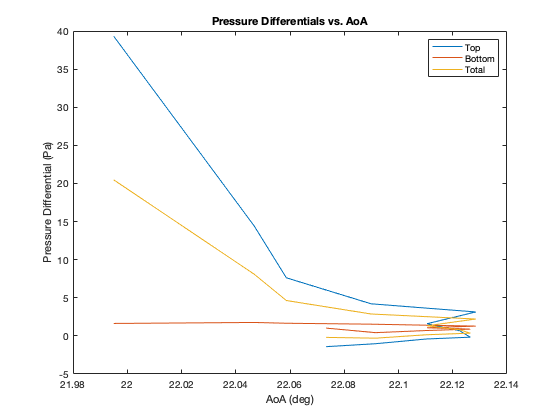

figure
plot(AoA, Pdiff_top)
hold on
plot(AoA, Pdiff_bot)
plot(AoA, Pdiff)
title('Pressure Differentials vs. AoA')
ylabel('Pressure Differential (Pa)')
xlabel('AoA (deg)')
legend('Top', 'Bottom', 'Total')

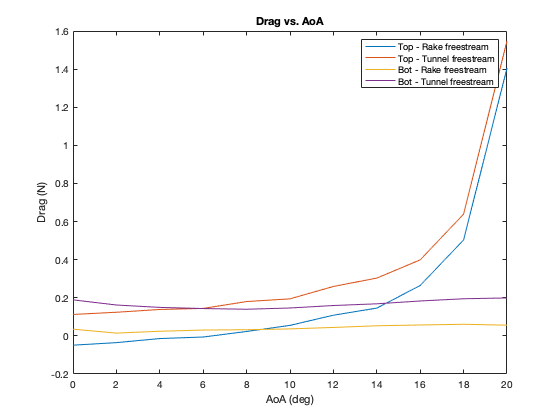


%saveas(gcf,'Av_Pressure_vs_AoA.png')

figure % comparing rake and tunnel drags
plot(AoA, drag_top_rake)
hold on
plot(AoA, drag_top_tunnel)
plot(AoA, drag_bot_rake)
plot(AoA, drag_bot_tunnel)
title('Drag vs. AoA')
ylabel('Drag (N)')
xlabel('AoA (deg)')
legend('Top - Rake freestream', 'Top - Tunnel freestream', ...
    'Bot - Rake freestream', 'Bot - Tunnel freestream')

Intuitively, the bottom surfaces do not measure noticable pressure differences with increasing AoA as both the bottom freestream tube and bottom rake tubes are exposed to relatively clean air with the wing out of the way above the path of oncoming air. Conversely, the top side of the rake experiences significantly higher drag since the top rake tubes are completely obstructed by the wing. 

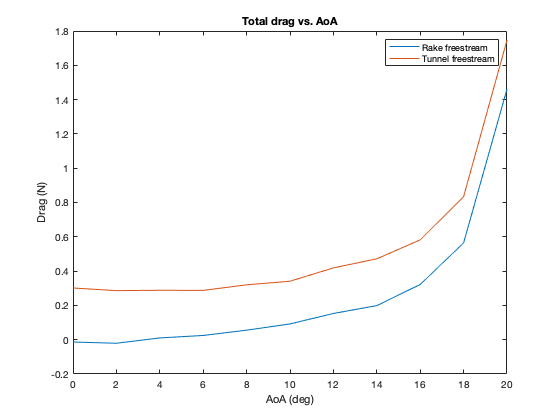

figure % total drags
plot(AoA, drag_rake(1,:))
hold on
plot(AoA, drag_raketunnel(1,:))
title('Total drag vs. AoA')
ylabel('Drag (N)')
xlabel('AoA (deg)')
legend('Rake freestream', 'Tunnel freestream')

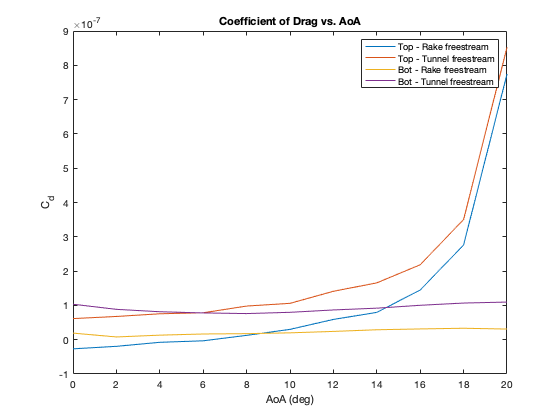

figure % comparing rake and tunnel drags
plot(AoA, cd_top_rake(1,:))
hold on
plot(AoA, cd_top_tunnel(1,:))
plot(AoA, cd_bot_rake(1,:))
plot(AoA, cd_bot_tunnel(1,:))
title('Coefficient of Drag vs. AoA')
ylabel('C_d')
xlabel('AoA (deg)')
legend('Top - Rake freestream', 'Top - Tunnel freestream', ...
    'Bot - Rake freestream', 'Bot - Tunnel freestream')

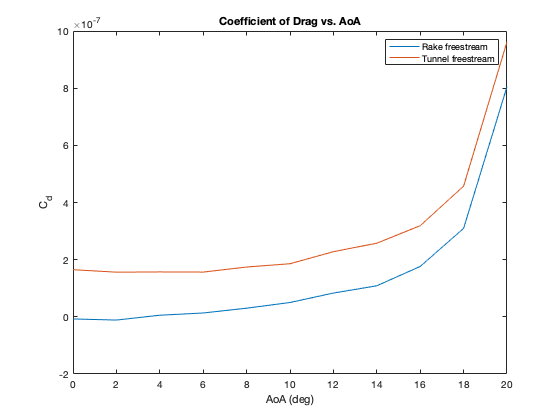


figure % total drags
plot(AoA, cd_rake(1,:))
hold on
plot(AoA, cd_raketunnel(1,:))
title('Coefficient of Drag vs. AoA')
ylabel('C_d')
xlabel('AoA (deg)')
legend('Rake freestream', 'Tunnel freestream')

    Again similar to part 1, Anderson's method and the drag rake values will now be compared against data from XFLR5.

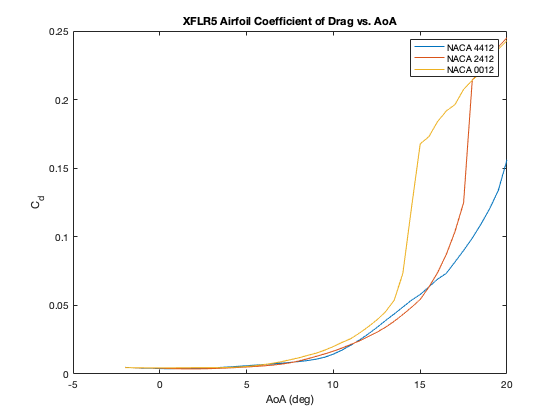

% importing XFLR5 data
mu = 1.983E-5; % dynamic viscosity of air (since test conditions close to STP assume STP)
l = 0.154; % m - wing length

dr_4412_aoa = load('NACA 4412_dr_4412_aoa.txt');
dr_2412_aoa = load('NACA 2412_dr_2412_aoa.txt');
dr_0012_aoa = load('NACA 0012_dr_0012_aoa.txt');

AoA1 = dr_4412_aoa(:,1); % deg - angle of attack vector
AoA2 = dr_2412_aoa(:,1); % deg - angle of attack vector
AoA3 = dr_0012_aoa(:,1); % deg - angle of attack vector

Re = 2.28E5; % Reynolds number for tests

cd_4412_aoa = dr_4412_aoa(:,4);
cd_2412_aoa = dr_2412_aoa(:,4);
cd_0012_aoa = dr_0012_aoa(:,4);

mu = 1.983E-5; % dynamic viscosity of air (since test conditions close to STP assume STP)
l = 0.154; % m - wing length
t = l/12; % m - finding airfoil thickness from length

speed = Re*mu / (rho*l); % convert to m/s

% finding drag
d_4412_aoa = 0.5*rho*t*cd_4412_aoa*speed.^2;
d_2412_aoa = 0.5*rho*t*cd_2412_aoa*speed^2;
d_0012_aoa = 0.5*rho*t*cd_0012_aoa*speed^2;

figure
plot(AoA1,cd_4412_aoa)
hold on
plot(AoA2,cd_2412_aoa)
plot(AoA3,cd_0012_aoa)
title('XFLR5 Airfoil Coefficient of Drag vs. AoA')
xlabel('AoA (deg)')
ylabel('C_d')
legend('NACA 4412', 'NACA 2412', 'NACA 0012')

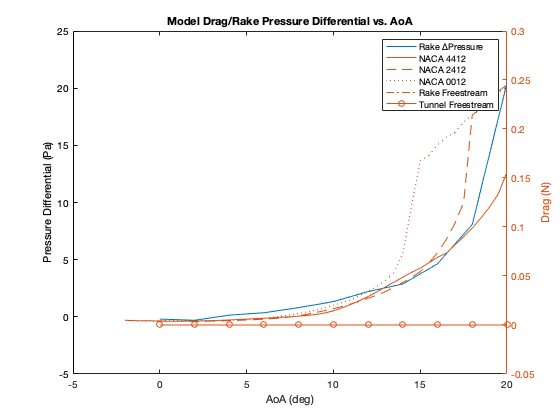

figure
plot(AoA, Pdiff(1,:))
hold on
ylabel('Pressure Differential (Pa)')
yyaxis right
plot(AoA1, d_4412_aoa)
plot(AoA2, d_2412_aoa)
plot(AoA3, d_0012_aoa)
plot(AoA, drag_rake(1,:))
plot(AoA, drag_raketunnel(1,:))
title('Model Drag/Rake Pressure Differential vs. AoA')
ylabel('Drag (N)')
xlabel('AoA (deg)')
legend('Rake ∆Pressure', 'NACA 4412', 'NACA 2412', 'NACA 0012', ...
    'Rake Freestream', 'Tunnel Freestream')

    Similarly to part 1, the minimization point(s) of the average pressure differential in the rake and the drag polars from XLFR5 line up quite well at equal AoAs (around 2 degs). This clearly shows that the drag rake design is sound and that the method for finding the minimum drag by minimizing the pressure differential over the rake is effective. 

### Conclusions

    As evidenced by good correlation between minimum pressure differential and minimum drag as well as the basic trends but not numerically accurate correlations between XFLR5's drag models and Anderson's drag model, it is concluded that Akaflieg SLO drag rake design is sound in design and that the method for drag estimation from Anderson is acceptable for a very rough approximation of drag force. Although this generation of drag rake only measures differential pressure, future iterations of drag rakes should consider adding a reliable static source, perhaps through a trailing cone to allow for drag estimations (rather than just drag minimizations) at various flight regimes. 

This test would not have been possible without help from Dr. Iscold, Adam Waldemarson, Will Bergman, and the other members of Akaflieg SLO who have helped with drag rake. My biggest thanks to you all.